# Sistemas de Visión Artificial

# **Práctica 2. Técnicas Básicas de Procesamiento de Imágenes**

**Autor(es): Franck Michael Fierro Chicaiza**

**Fecha: 10/10/2023**

**La práctica se completará en este mismo fichero .mlx,** añadiendo el nombre del autor/autores del grupo, la fecha, e insertando el código y los comentarios pertinentes en cada apartado. Se visualizarán los resultados conjuntamente con "subplot" cuando sea conveniente. Para evitar problemas al visualizar las imágenes (pueden "perderse" imágenes al superponerse las de los siguientes apartados y/o mostrarse en apartados posteriores), antes de cada "imshow" es necesario incluir un comando "figure", y los distintos apartados deben estar separados en secciones independientes insertando un "section break" entre ellas (en el código se añade escribiendo "%%" y también se puede añadir pinchando en la opción correspondiente del menú).

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

1.      Utilice "imageinfo" para averiguar el formato (RGB, mapa de colores indexado, etc.) de una imagen en color ("canoe.tif", "peppers.png", ...) y ábrala utilizando las variables adecuadas ("J", "X", "map", etc...).

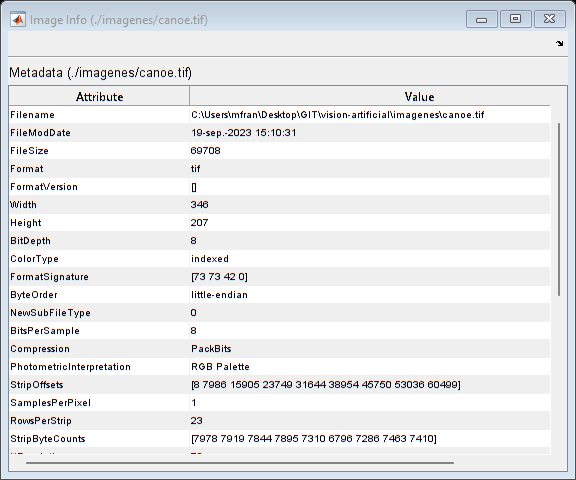

clear all
close all

% Obtenemos informacion de la imagen
imageinfo('./imagenes/canoe.tif')

**Comentario:**

**Podemos obtener de la información que la imagen es indexada por lo que tendra un mapa de colores asociado a ella.**

2.	Visualice la imagen que acaba de leer.

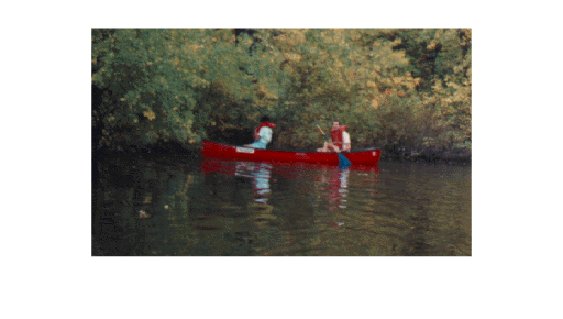

% Leemos y mostramos la imagen
[X, map] = imread('./imagenes/canoe.tif');
imshow(X, map)

3. Convierta la imagen anterior en una imagen en escala de grises y almacénela en un array llamado "I". Indique el rango de valores en los que se cuantifica la luminancia (niveles de gris mínimo y máximo) de la imagen resultante.

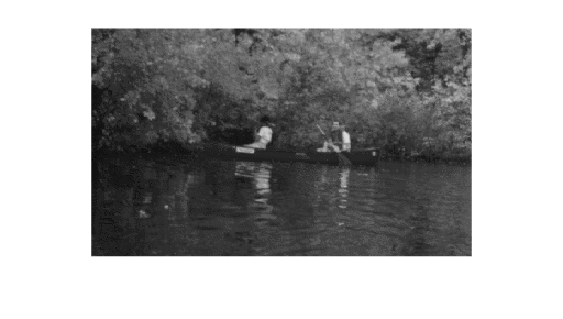

% Convertimos la imagen anterior a escala de grises
I = ind2gray(X, map);
imshow(I)

% Minimo valor de la imagen
minLuminancia = min(I(:))

minLuminancia = uint8
0

% Maximo valor de la imagen
maxLuminancia = max(I(:))

maxLuminancia = uint8
218

% Rango
rango = maxLuminancia - minLuminancia

rango = uint8
218

**Comentario:**

**La imagen contiene píxeles cuyos valores oscilan entre 0 y 218**

4. Averigüe las dimensiones de nuestra imagen "I" (filas x columnas).

% Obtnemos las dimensiones de la imagen
[filas, columnas, profundidad_color] = size(I)

filas = 207

columnas = 346

profundidad_color = 1

**Comentario:**

**Dimensiones de la imagen 207x346**

5. Muestre el histograma de la imagen "I".

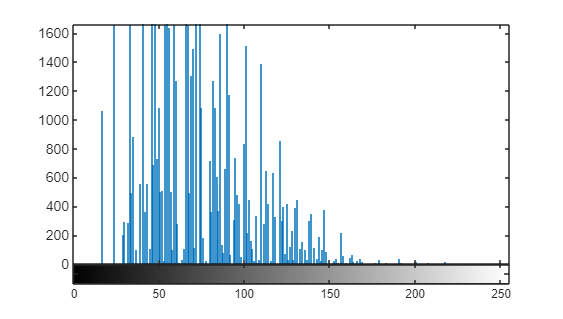

% Obtenemos el histograma de la imagen
imhist(I) 

6. Modifique el brillo y el contraste de la imagen "I" y visualice las imágenes resultantes y sus histogramas.

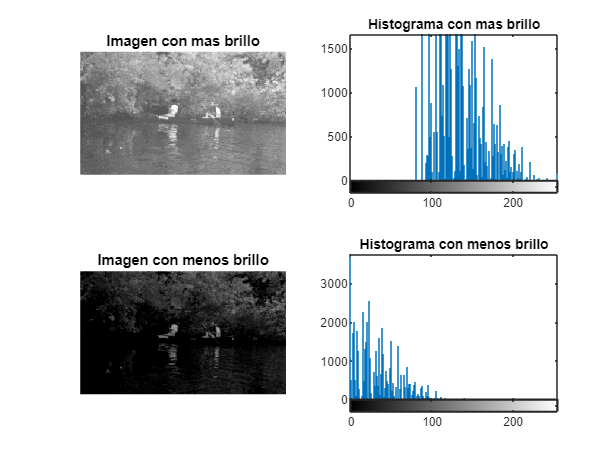

% Brillo
I_b_alto = imadjust(I,[0 0.75], [0.25 1]); % Mas brillo
I_b_bajo = imadjust(I,[0.2 1], [0 0.8]);   % Menos brillo
% Tambien se puede I - x / I + x

% Mostramos el resultado
figure
subplot(2,2,1), imshow(I_b_alto); title('Imagen con mas brillo');
subplot(2,2,2), imhist(I_b_alto); title('Histograma con mas brillo');
subplot(2,2,3), imshow(I_b_bajo); title('Imagen con menos brillo');
subplot(2,2,4), imhist(I_b_bajo); title('Histograma con menos brillo');

**Comentario:**

**Para modificar el brillo de una imagen se utiliza la función 'imadjust'. Para aumentar el brillo, se desplazan los valores de intensidad de la imagen hacia valores más altos, mientras que para reducir el brillo, se desplazan hacia valores más bajos**.

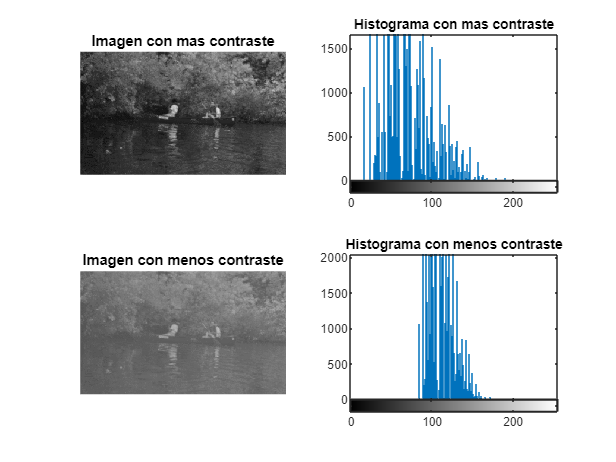

% Contraste
I_c_alto = imadjust(I,[minLuminancia/256 maxLuminancia/256], [0 1]); 
I_c_bajo = imadjust(I,[0 1], [0.3 0.8]); 

% Mostramos el resultado
figure
subplot(2,2,1), imshow(I_c_alto); title('Imagen con mas contraste');
subplot(2,2,2), imhist(I_c_alto); title('Histograma con mas contraste');
subplot(2,2,3), imshow(I_c_bajo); title('Imagen con menos contraste');
subplot(2,2,4), imhist(I_c_bajo); title('Histograma con menos contraste');

**Comentario:**

**Para ajustar el contraste, también se utiliza la función 'imadjust'. En este caso, para aumentar el contraste, se expande el rango de intensidades de la imagen y se distribuyen a lo largo de todo el rango de intensidades, lo que nos permite resaltar características de la imagen. Por otro lado, para reducir el contraste, se estrecha el rango de intensidades de la imagen y como podemos ver las caracteristicas disminuyen.**

7. Realice una binarización de la imagen "I" con un umbral cuyo valor sea aproximadamente la mitad de su rango de grises y visualice el resultado.

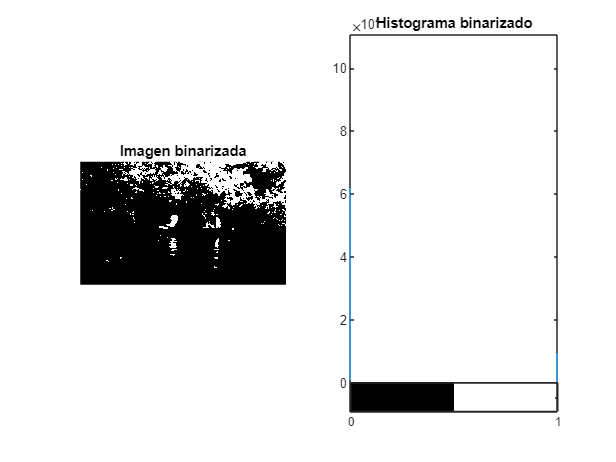

% Establecemos el umbral
umbral = rango / 2;
% Obtenemos la imagen binarizada
I_bin = I > umbral;

figure
subplot(1,2,1), imshow(I_bin); title('Imagen binarizada');
subplot(1,2,2), imhist(I_bin); title('Histograma binarizado');

**Comentario:**

**Al binarizar la imagen, las intensidades de la misma se asignan a dos valores, 0 y 1, basándose en un umbral previamente seleccionado.**

8. Obtenga el negativo de la imagen "I" obtenida en el punto 3.

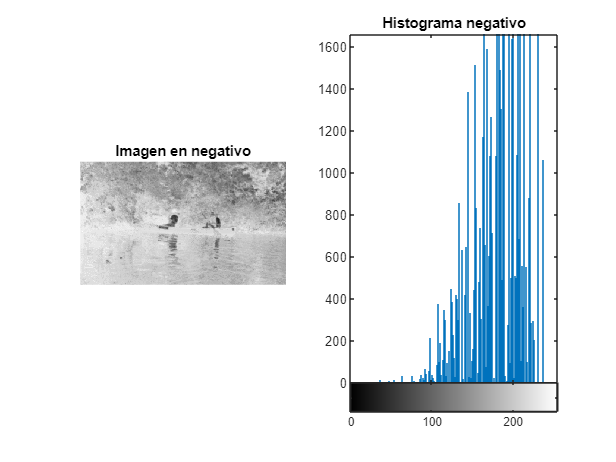

% Obtenemos el negativo de la imagen
I_neg = 255 - I;

figure
subplot(1,2,1), imshow(I_neg); title('Imagen en negativo');
subplot(1,2,2), imhist(I_neg); title('Histograma negativo');

**Comentario:**

**Al realizar el negativo se invierten los valores de intensidad de la imagen, cambiando los pixeles claros por oscuros y los mas oscuros se volveran mas claros.**

9. Obtenga y muestre tres versiones ruidosas de la imagen "I":

   (a) con ruido de distribución uniforme 'speckle', "Is",

   (b) con ruido de tipo 'sal y pimienta' de densidad de ruido 5%, "Isp",

   (c) con ruido de tipo gaussiano de media cero y varianza 0.01, "Ig".

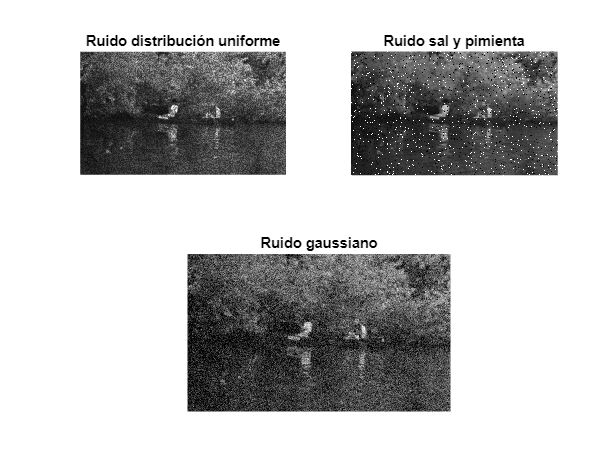

% a. ruido de distribucion uniforme
Is = imnoise(I, 'speckle');

% b. ruido de sal y pimienta
Isp = imnoise(I, 'salt & pepper', 0.05);

% c. ruido gaussiano
Ig = imnoise(I, 'gaussian', 0, 0.01);

figure
subplot(2,2,1), imshow(Is); title('Ruido distribución uniforme');
subplot(2,2,2), imshow(Isp); title('Ruido sal y pimienta');
subplot(2,1,2), imshow(Ig); title('Ruido gaussiano');

**Comentario:**

**A través de la función 'imnoise', hemos podido simular tres tipos de ruido en una misma imagen, lo que nos permite modificar el tipo de ruido introducido y su nivel.**

10. Partiendo de la imagen contaminada con ruido gaussiano anterior, "Ig", fíltrela utilizando la media del entorno de vecindad, primero con un entorno de vecindad de 3x3 y luego con uno de 5x5, comparando los resultados obtenidos. Justifique sus conclusiones.

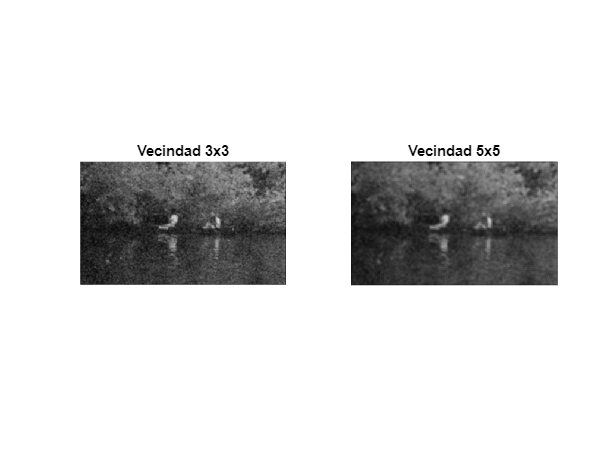

% Convertimos los valores de la imagen en el rango (0, 1)
Ig = im2double(Ig);
% Filtramos la imagen con ruido por vecindad
Ig_m3 = filter2(fspecial('average',3), Ig);
Ig_m5 = filter2(fspecial('average',5), Ig);

figure
subplot(1,2,1), imshow(Ig_m3); title('Vecindad 3x3');
subplot(1,2,2), imshow(Ig_m5); title('Vecindad 5x5');

**Comentario:**

**Comparando los resultados, podemos observar que al usar un filtro de vecindad '3x3', la imagen no pierde nitidez, pero tampoco se elimina el ruido de la imagen. En cambio, al aplicar el filtro '5x5', la imagen se vuelve más borrosa pero con menos ruido. Por lo tanto, a mayor tamaño de vecindad, se reduce el ruido, pero también se disminuye la nitidez de la imagen.**

11. Partiendo de la imagen contaminada con ruido sal y pimienta en el apartado anterior, "Isp":

    (a) Filtre "Isp" con un filtro de media del entorno de vecindad.

    (b) Filtre "Isp" con un filtro de mediana.

    (c) Compare los resultados: ¿qué tipo de filtrado es más adecuado para este tipo de ruido?

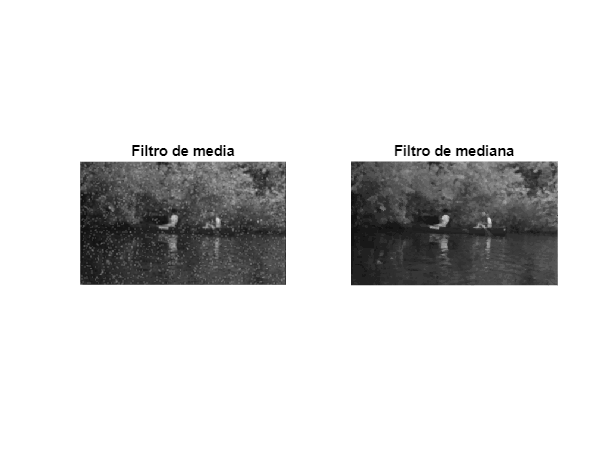

% Convertimos los valores de la imagen en el rango (0, 1)
Isp = im2double(Isp);
% Filtramos por media
Isp_media = filter2(fspecial('average',3), Isp);
% Filtramos por mediana
Isp_mediana = medfilt2(Isp, [3 3]);

figure
subplot(1,2,1), imshow(Isp_media); title('Filtro de media');
subplot(1,2,2), imshow(Isp_mediana); title('Filtro de mediana');

**Comentario:**

**De los resultados obtenidos, podemos observar que el filtro por media de vecindad aún contiene ruido en la imagen, mientras que el filtro por mediana de vecindad produce un resultado de muy buena calidad de imagen. Por lo tanto, podemos concluir que realizar la mediana de la vecindad de un píxel es más efectivo que realizar la media cuando se trata de eliminar el ruido sal y pimienta.**

12. A partir de la imagen original "blood1.tif", obtenga 16 imágenes diferentes con ruido gaussiano de media cero y varianza 0.05. Utilizando la función "imwrite", guárdelas en ficheros con sus respectivos nombres (por ejemplo, "ruidosa1.bmp", ..., "ruidosa16.bmp").

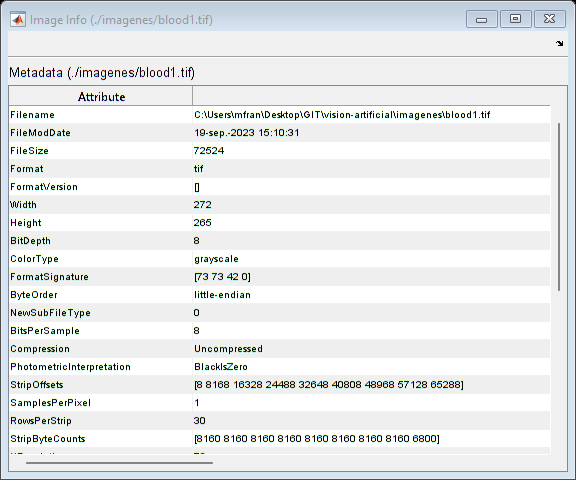

% Obtenemos la imagen y su informacion
X = imread('./imagenes/blood1.tif');
imageinfo('./imagenes/blood1.tif')

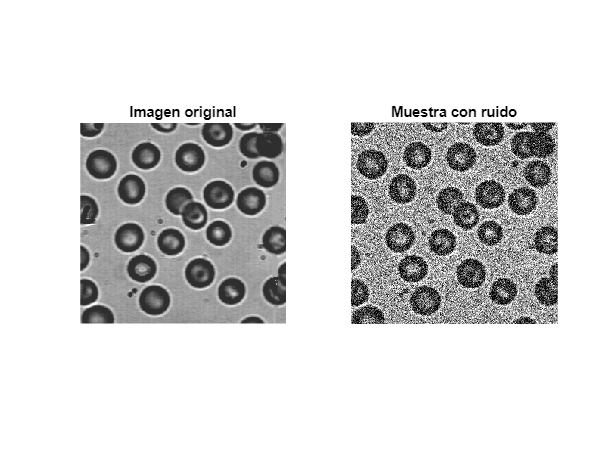


% Creamos una carpeta para almacenar las imagenes con ruido
folder = './Practica2/Ejercicio12';
if ~isfolder(folder)
    mkdir(folder)   % Si no existe se crea
end

% Con un bucle creamos las 16 imagenes y las guardamos
for i = 1:16
    X_ruido = imnoise(X, 'gaussian', 0, 0.05);
    imwrite(X_ruido, fullfile(folder, sprintf('ruidosa%d.bmp', i)));
end

figure
subplot(1,2,1), imshow(X); title('Imagen original');
subplot(1,2,2), imshow(X_ruido); title('Muestra con ruido');

**Comentario:**

**De la información de la imagen, podemos obtener que es una imagen en escala de grises.**

13. Realice pruebas de filtrado de ruido usando la técnica de promediado de imágenes sobre las imágenes creadas en el punto anterior. Para ello, promedie en primer lugar con 4 imágenes ruidosas, luego con 8 y, finalmente, con las 16. Compare visualmente los resultados y coméntelos.

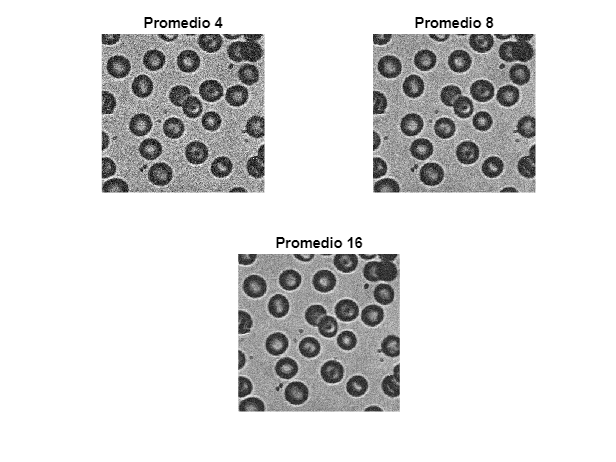

% Cargamos las imagenes
imgs_ruido = cell(16,1);
for i = 1:16
    imgs_ruido{i} = imread(fullfile(folder, sprintf('ruidosa%d.bmp', i)));
end

% Promediamos las imagenes
% Para 4 imagenes
n = 4;
img_promedio4 = uint8(mean(cat(n, imgs_ruido{1:n}), n));

% Para 8 imagenes
n = 8;
img_promedio8 = uint8(mean(cat(n, imgs_ruido{1:n}), n));

% Para 16 imagenes
n = 16;
img_promedio16 = uint8(mean(cat(n, imgs_ruido{1:n}), n));

figure, 
subplot(2,2,1), imshow(img_promedio4); title('Promedio 4');
subplot(2,2,2), imshow(img_promedio8); title('Promedio 8');
subplot(2,1,2), imshow(img_promedio16); title('Promedio 16');

**Comentario:**

**Como se puede observar, cuanto mayor es el número de imágenes que utilizamos para el promediado, mayor será la reducción del ruido presente en la imagen. La desventaja radica en que todas las imágenes deben ser idénticas.**

14. Cargue la imagen "bazo.bmp" y muestre su histograma. Compruebe que se trata de una imagen con poco contraste. Convierta la imagen a escala de grises y luego ecualice su histograma uniformemente. Visualice la imagen resultante y su histograma y comente las diferencias con la imagen original.

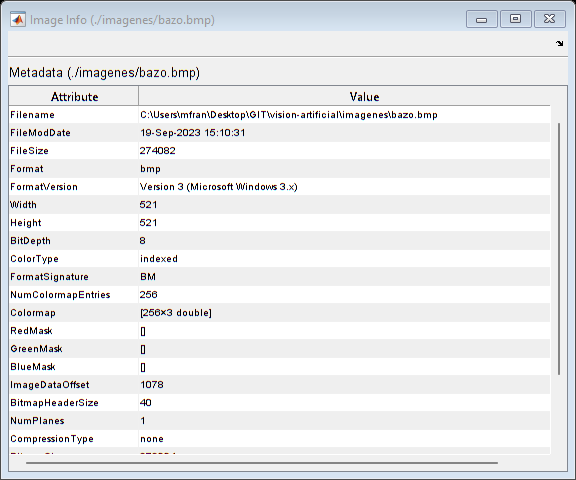

% obtenemos la imagen y su informacion
[X, map] = imread('./imagenes/bazo.bmp');
imageinfo('./imagenes/bazo.bmp')

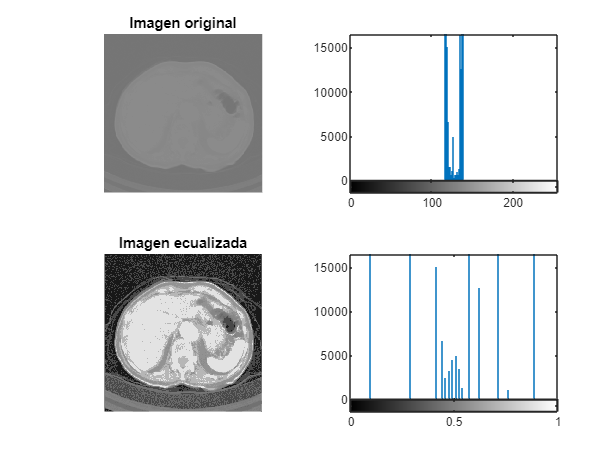

% Convertimos la imagen a escala de grises
% Convertimos los valores de la imagen a valores entre el rango (0,1)
I = ind2gray(X, map);
% Ecualizamos el histograma de la imagen
I_ecu = histeq(I);

figure, 
subplot(2,2,1), imshow(X, map); title('Imagen original');
subplot(2,2,2), imhist(X);
subplot(2,2,3), imshow(I_ecu); title('Imagen ecualizada');
subplot(2,2,4), imhist(I_ecu);

**Comentario:**

**Como primer dato obtenemos que la imagen es indexada por lo que tiene un mapa de colores asociado**

**De los resultados, podemos observar en el histograma de la imagen original, los valores de intensidad se concentran en un rango muy pequeño, lo que resulta en una imagen con poco contraste. Por otro lado, al ecualizar el histograma, los diferentes valores de intensidad se distribuyen a lo largo de todo el rango completo del histograma, lo que permite apreciar la imagen de una mejor manera y resaltar los detalles en la misma.**

15. Disminuya el brillo de la imagen "bazo.bmp" hasta que el nivel de gris más bajo sea 0 y realice sobre esa imagen una corrección gamma. Pruebe con distintos valores de gamma y analice el efecto de cada uno sobre la imagen de salida.

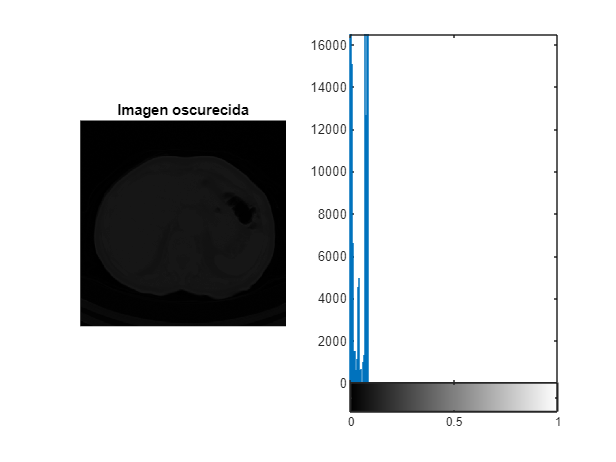

% Obtenemos el rango de valores de intensidad de la imagen
vmin=min(min(I)); 
vmax=max(max(I));

% Disminuimos el brillo de la imagen
I_osc = imadjust(I, [vmin vmax], [0 vmax-vmin]);

figure, 
subplot(1,2,1), imshow(I_osc); title('Imagen oscurecida');
subplot(1,2,2), imhist(I_osc);

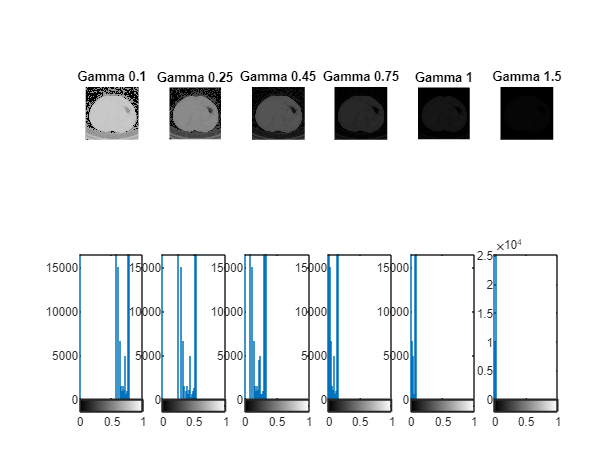

% Establecemos valores para gamma
gamma = [0.1, 0.25, 0.45, 0.75, 1, 1.5];

figure,
for i = 1:6
    % Realizamos la correccion gamma
    I_gamma = imadjust(I_osc, [], [], gamma(i));
    subplot(2,6,i), imshow(I_gamma); title(sprintf('Gamma %s', num2str(gamma(i))));
    subplot(2,6,i+6), imhist(I_gamma);
end

**Comentario:**

**Tras realizar pruebas con distintos valores de gamma, se puede observar lo siguiente: el valor 1 da como salida la imagen de entrada sin modificación alguna. Por otro lado, se observa que para valores menores de 1, cuanto menor es el valor de gamma, la imagen se aclara y se ajusta el contraste. Mientras que, para valores superiores a 1, la imagen se oscurece.**

**En este caso, también se observa cómo, con un valor de gamma menor que uno, aumenta el contraste en una imagen oscura, mientras que un valor de gamma mayor que 1 suele utilizarse en imágenes claras para mejorar el contraste que no es el caso de la imagen que estudiamos en este apartado.**

16. Lea la imagen "venas.tif" y rótela un ángulo de 50 grados (por ejemplo), utilizando los métodos de interpolación "nearest" y "bicubic" (parámetros de la función "imrotate"). Aumente las imágenes lo suficiente para ver las diferencias entre ambos resultados y compárelos.

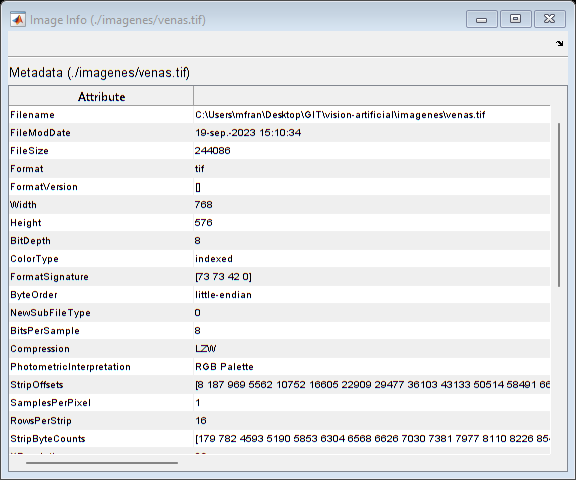

% Obtenemos la imagen y su informacion
[X, map] = imread('./imagenes/venas.tif');
imageinfo('./imagenes/venas.tif')

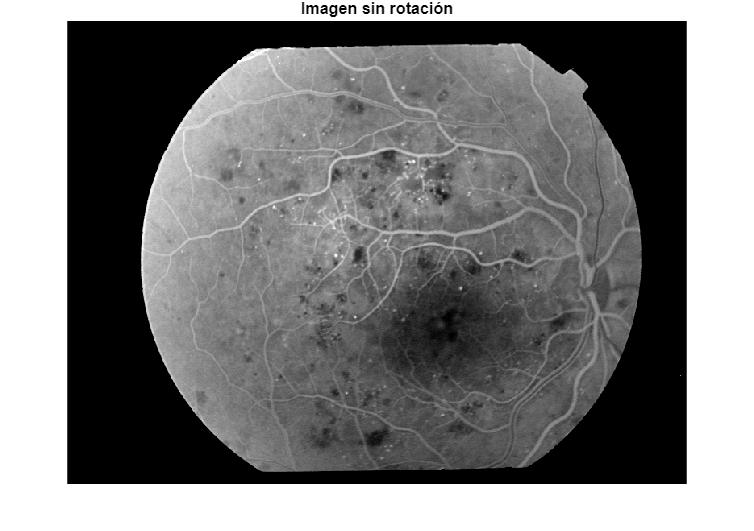

% Rotamos la imagen con el metodo nearest y bicubic
X_rot_nearest = imrotate(X, 50, "nearest");
X_rot_bicubic = imrotate(X, 50, "bicubic");

figure, 
imshow(X, map); title('Imagen sin rotación');

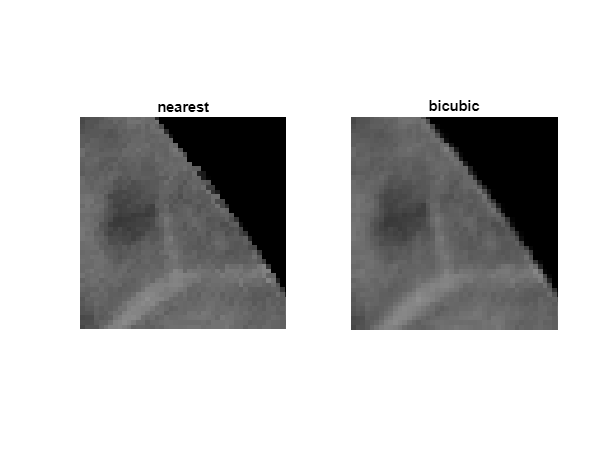

figure,
subplot(1,2,1), imshow(X_rot_nearest, map); title('nearest');
subplot(1,2,2), imshow(X_rot_bicubic, map); title('bicubic');

subplot(1,2,1)
xlim([701.5 745.7])
ylim([266.0 311.5])
subplot(1,2,2)
xlim([701.5 745.7])
ylim([266.0 311.5])

**Comentario:**

**Podemos comparar los resultados al acercarnos al borde del objeto en la imagen. Con el método 'nearest', obtenemos un borde más abrupto, ya que cada píxel se construye basándose en el píxel más cercano de la imagen original. Por otro lado, el método 'bicubic' utiliza una aproximación polinómica para calcular el valor de cada píxel, teniendo en cuenta un área más amplia de píxeles, lo que resulta en una imagen más uniforme y con un mayor suavizado. El primer método es más rápido que el segundo debido a su menor carga computacional, pero el segundo método ofrece una mejor calidad de imagen.**